# **Experiência 5 - Como inserir marca d’água em um sinal de áudio? **

## **Guilherme Reis da Silva 10773700**

## **Gabriel Tavares Ferrarez 10773801** 

# PARTE 1 - Sistema de marca d’água visto como um problema de comunicação digital

Nessa etapa iremos codificar a imagem em códigos binários e adicionar ruído gaussiano a ela para simular uma transmissão desses dados por rede

## LETRA A - Criação da mensagem

Primeiramente iremos ler a imagem, transformar a matriz em um vetor com todos os dados, mudar os valores de inteiros de 0 até 255 para binários de 8 bits e por fim mudar esse binário de {0,1} para {-1,+1}.

Com isso, teremos a mensagem que queremos enviar. Essa mensagem será codificada para o envio na próxima etapa.

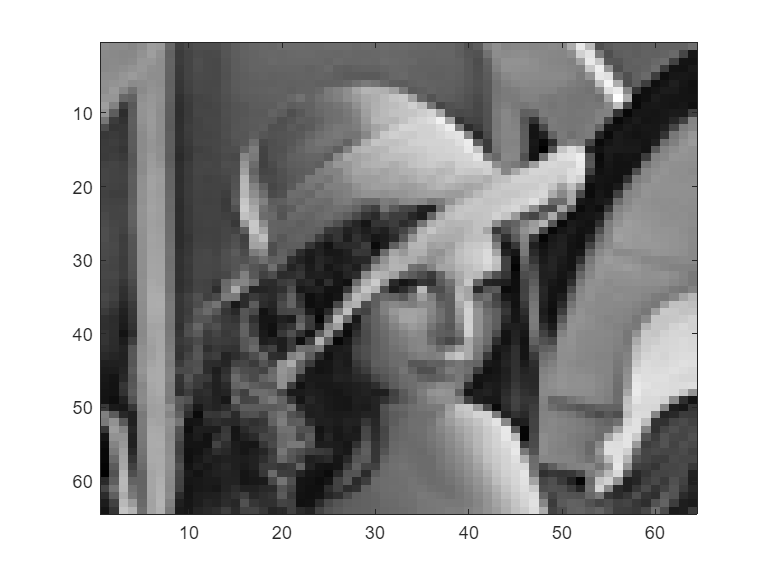

lenna = imread('lenna64.jpg');
imagesc(lenna);
colormap(gray);

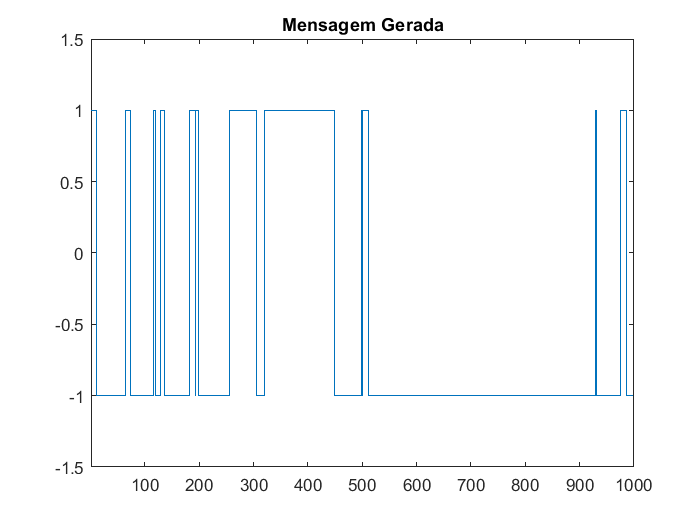

M = 64*64*8;

lenna_bin = dec2bin(lenna);
lenna_col = reshape(lenna_bin,2^15,1);
am = 2*str2num(lenna_col) - 1;

stairs(am)

xlim([1 1000])
ylim([-1.5 1.5])
title("Mensagem Gerada")

## LETRA B - Geração do sinal Emitido

Aqui será gerado o sinal de marca d'agua mais simples. Ele será composto pela concatenação de códigos **+c **(bit 1) ou **-c **(bit 0) ao longo do tempo. 

Para gerar esse sinal, primeiro criamos o código **c** como um vetor de números aleatórios apenas com +1 e -1. Depois multiplicamos esse vetor por cada bit {-1,+1} da mensagem gerada anteriormente e assim temos o vetor de sinal emitido **v**.

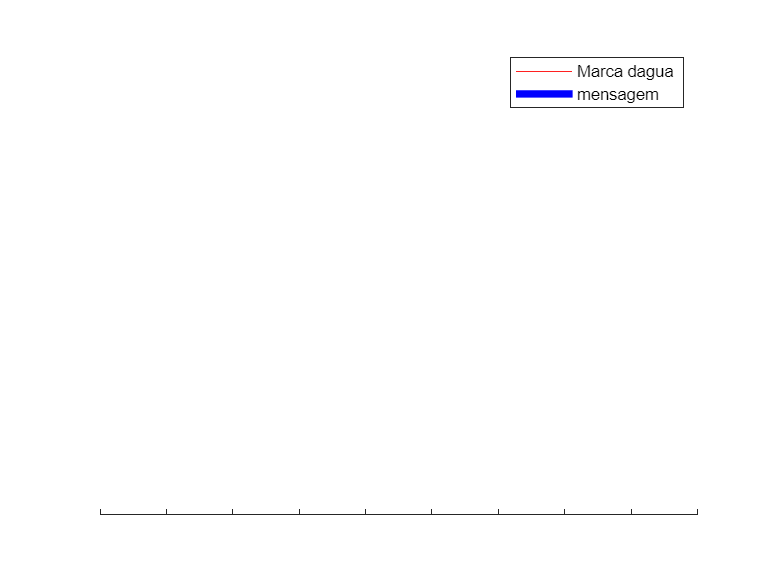

fa = 44.1e3;
R = 100;
g = 1;
rand('seed',12345);
Nb = fa / R;

c = 2*round(rand(Nb,1)) - 1; % codigo

v = kron(am,c); % sinal modulado
bm_exp = kron(am, ones(Nb,1)); %repetir cada ponto do am Nb vezes

figure();
ylim([-2 2]);
hold on
stairs(v(253*Nb:255*Nb +1), 'color', 'r');
stairs(bm_exp(253*Nb:255*Nb +1), 'linewidth', 4, 'color', 'b');
title('Marca dagua e mensagem')
legend('Marca dagua', 'mensagem')
hold off

Agora vamos analisar o efeito do espalhamento de frequência do sinal que geramos.

O sinal inicial da mensagem é um sinal de banda estreita (como vemos no gráfico). Quando fazemos a multiplicação entre os sinais, a densidade de potência se espalha por toda a frequência.

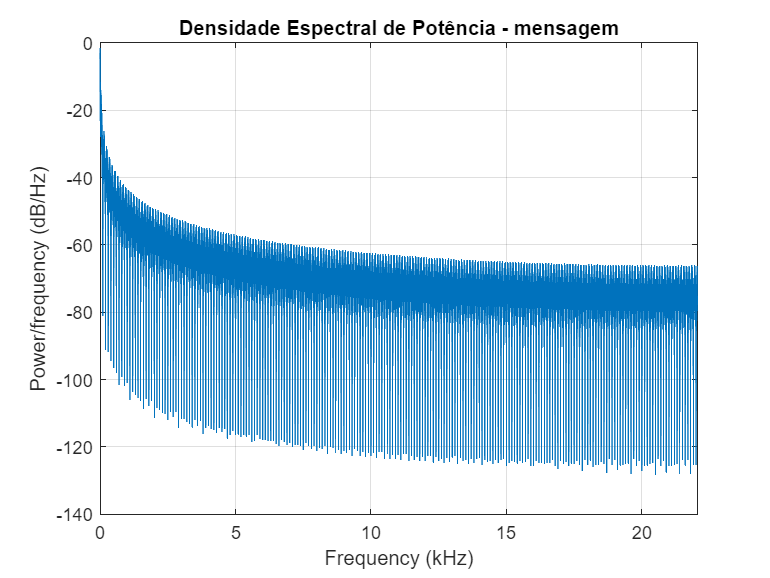

pwelch(bm_exp, [],[],[],fa);
title("Densidade Espectral de Potência - mensagem")

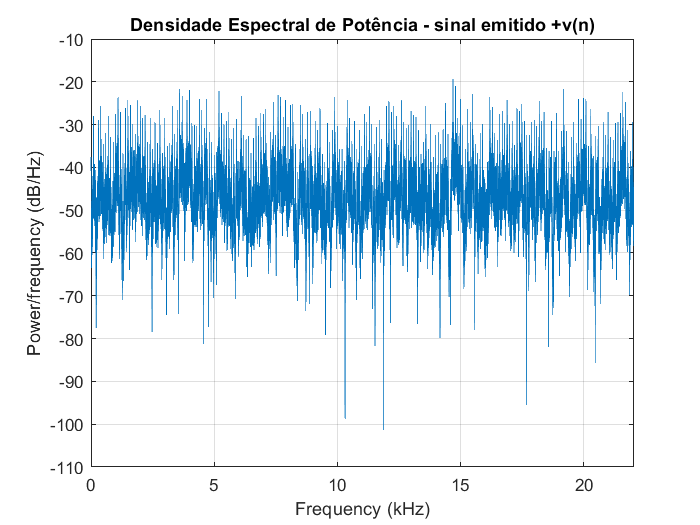

pwelch(v, [],[],[],fa);
title("Densidade Espectral de Potência - sinal emitido +v(n)")

## LETRA C

Aqui iremos gerar um sinal de audio para ser somado ao sinal de marca d'agua. Nesse exemplo, o sinal será um ruído gaussiano com **SNR = -20dB** 

pot_v = sum(v.*v)/length(v);

SNR = -20;
pot_ruido = pot_v*10^(-SNR/10);

x = sqrt(pot_ruido)*randn(length(v),1); % ruido branco gaussiano

y = x + g*v; % sinal transmitido pelo canal

## LETRA D - Soma do sinal + Ruído

Aqui vamo somar o sinal de ruído gaussiano (música) com o sinal da mensagem para verificar a diferenaça entre os sinais

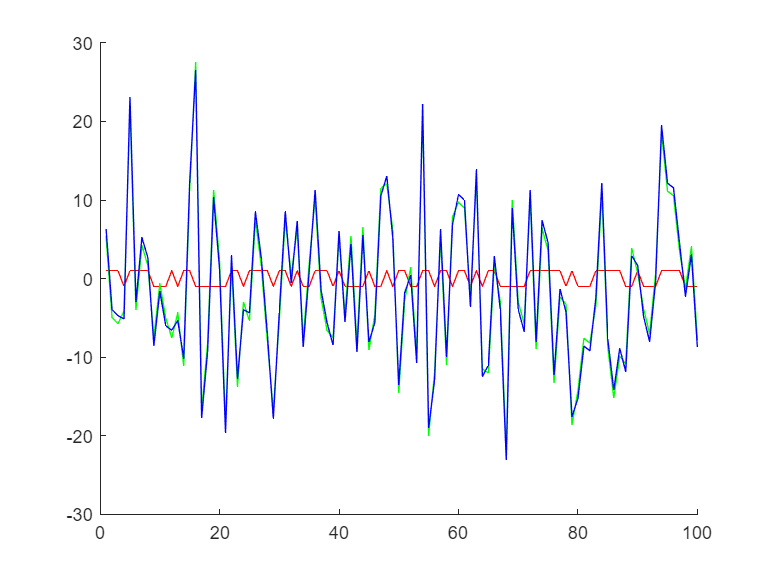

figure()
hold on
plot(v(1:100), 'color', 'r');
plot(x(1:100), 'color', 'g');
plot(y(1:100), 'color', 'b');
hold off

## LETRA E - Recuparação de códigos

A mensgame é recuperada fazendo a multiplicação entre os trechos de mensagem obtidos pelo código incial. Com isso é possível recuperar os bits transmitidos apenas verificando o sinal dessa multiplicação em cada bit

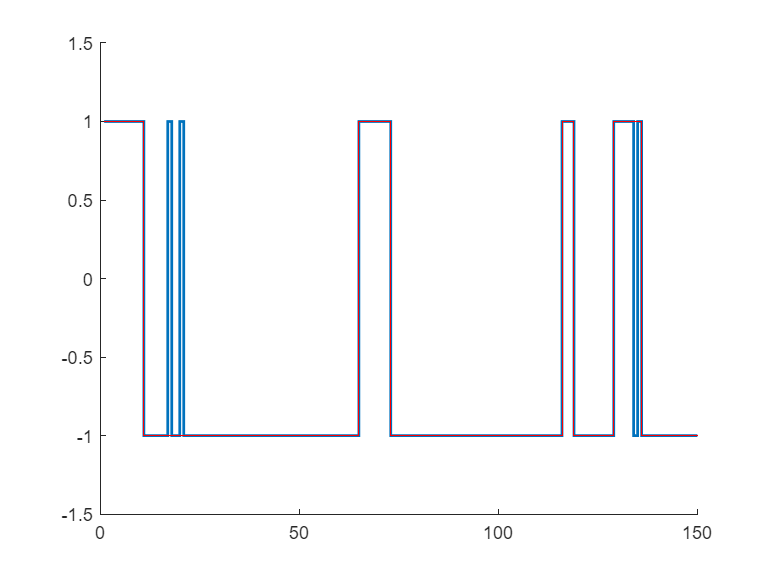

ym = reshape(y,Nb,32768);

alfam = transpose(ym)*c/Nb;
figure()
hold on;
stairs(sign(alfam), 'linewidth',1.5);
stairs(am, 'color', 'r');
hold off

xlim([0 150])
ylim([-1.5 1.5])

## LETRA F - Recuperação da imagem

Agora iremos aplicar o algoritimo a cima em toda a mensagem obtida e recuperar os bits originais. Depois de recuperar a mensagem, vamos reconstruir a imagem fazendo o processo inverso da construção. 

Além disso vamo calcular a taxa de erro de bits transmitidos (**BER**) para avaliar quão boa foi a transmissão

BER = sum(abs(sign(alfam) - am)/2)/length(am)

BER = 0.0189

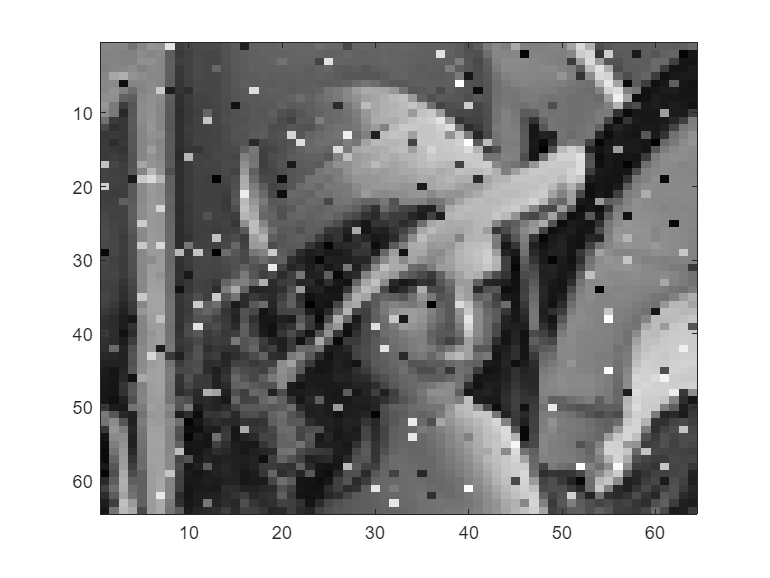


b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2);
lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

figure()
colormap(gray)
imagesc(nova_lenna)

## LETRA G - Mean Struct Similarity

Por fim iremos calcular a qualidade a imagem transmitida usando **MSSIM**

load('fspecial_matriz.mat')
mssim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255)

mssim = 0.7684

# PARTE 2 - Ajuste do ganho para detecção sem erro

## LETRA A - Transmissão em música

Aqui iremos misturar a marca d'agua com uma música real para aplicar os algorítimos de detecção de bits

[musica, fs] = audioread('BeethovenExp5.wav');

y_sem_ganho = musica + g*v; % sinal escondido na musica

% sound(musica(fs*5:fs*15),fs)

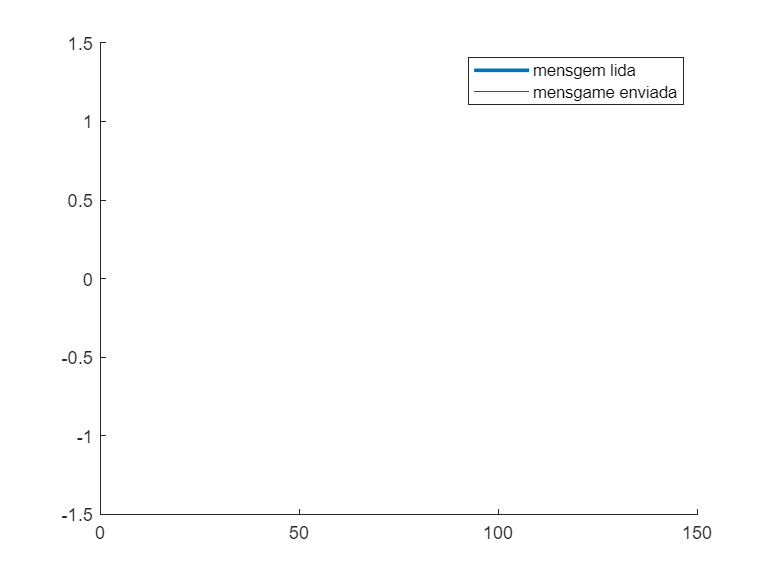


ym = reshape(y_sem_ganho,Nb,32768);

alfam = transpose(ym)*c/Nb;

figure()
hold on;
stairs(sign(alfam), 'linewidth',2);
stairs(am, 'color', 'r');
legend('mensgem lida', 'mensgame enviada');
hold off

xlim([0 150])
ylim([-1.5 1.5])

BER = sum(abs(sign(alfam) - am)/2)/length(am)

BER = 0

Depois de ter a mensagem enviada, vamo decodificar o sinal recebido e a imagem recebida é a seguinte

b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2);
lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

figure()
colormap(gray)
imagesc(nova_lenna)

A imagem está excelente, porém o som está extremamente ruidoso, o que invalida esta forma de transmissão.

y_lennaPerf_somRuim = y;

sound(y_sem_ganho(fa*5:fa*20), fs);

## LETRA B - Calculo do ganho

Aqui iremos variar o ganho de forma a ter a imagem perfeita tendo apenas o ganho necessário por trechos.

Vamos dividir o audio em trechos e em cada trecho vamos calcular o ganho necessário para a identificação do código sem erros.

x = musica;

Dg = 0.005;
g = zeros(M, 1);
sinal_marcadagua=zeros(M*Nb,1);

for m = 0:M-1
    beta=transpose(x(m*Nb + 1: (m+1)*Nb))*c/Nb;
    if am(m+1)==1
        if beta>=Dg
            g(m+1)=0;
        else
            g(m+1)=Dg - beta;
        end
    else
        if beta<-Dg
            g(m+1)= 0;
        else
            g(m+1)=Dg+beta;
        end
    end
    
    sinal_marcadagua(m*Nb + 1: (m+1)*Nb)= g(m+1)*v(m*Nb + 1 : (m+1)*Nb);
    % Esse ´e o sinal de marca d’´agua
end

y = musica + sinal_marcadagua;
y_semErro = y;

## LETRA C - Recuperação da Imagem

ym = reshape(y,Nb,32768);

alfam = transpose(ym)*c/Nb;
BER = sum(abs(sign(alfam) - am)/2)/length(am)

BER = 0

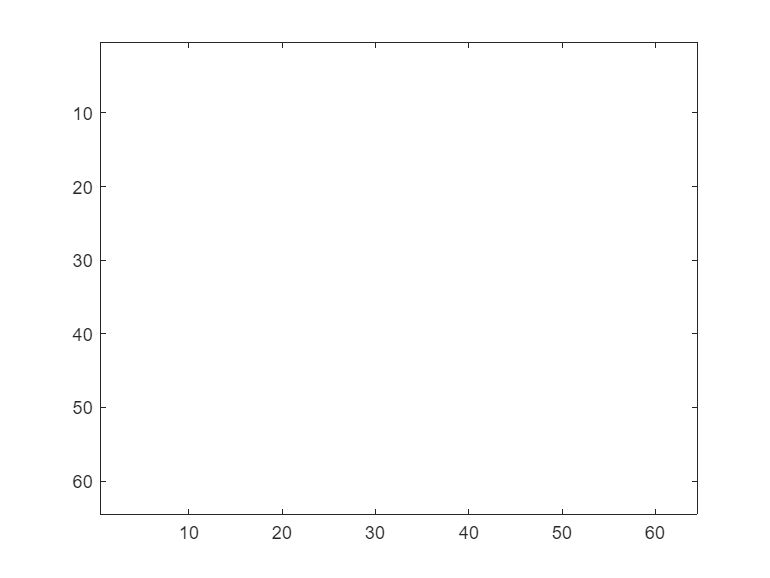


b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2);
lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

figure()
colormap(gray)
imagesc(nova_lenna)

mssim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255)

mssim = 1

sound(y_semErro(fa*5:fa*20), fs);

Nesse caso temos uma imagem também perfeito e com o ganho suficiente para a detecção sem erros. Esse ganho é mínimo necessário para não termos erros na transmissão. Apesar disso, o som do ruído ainda é bastante notável e até mais alto que a própria música.

# PARTE 3 - Tornando a marca d’água inaudível

Aqui iremos processar  a marca d'agua de forma a ter o ruído do sinal da mensagem inaudível. Para isso, iremos filtrar o ruído pela mascara de limiar psicoacústico em cada trecho do áudio.

## LETRA A - Criação da marca d'agua

Faremos um processo parecido com o ajuste de ganho do exercício anterior. Iremos dividir o audio em trechos de 512 amostras e para cada trecho vamos calcular a mascara psicoacustica desse trecho. Essa máscara servirá como uma espécie de ganho que o sinal de marca d'água recebe naquele trecho. Dessa forma esperamos ter o sinal da marca d'água baixo suficiente para não ouvirmos ele.

w = zeros(length(musica),1);
z = zeros(length(musica),1);
zs = zeros(50,1);
Nblocos = floor(length(musica)/512);

for i = (0:Nblocos-1)
    mascara = psychoacoustical_model( musica(i*512+1 : (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [w(i*512+1: (i+1)*512), zs] = filter(b0, ai ,v(i*512+1: (i+1)*512), zs);

    y(i*512+1: (i+1)*512) = w(i*512+1: (i+1)*512) + x(i*512+1: (i+1)*512);
end
y_inaudivel = y;

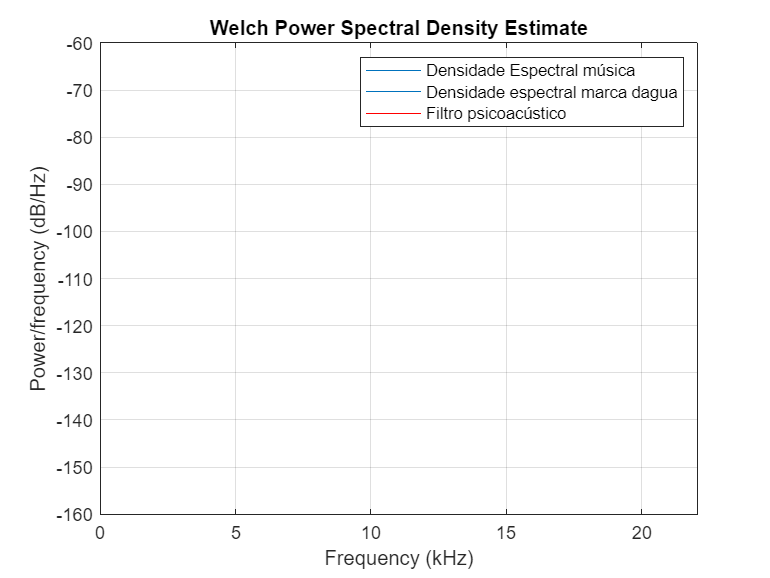

trecho = 512*10+1:512*11;
mascara = psychoacoustical_model( musica(i*512+1 : (i+1)*512) );
[b0, ai] = shaping_filter_design(mascara, 50);
[resp_psico, f] =freqz(b0, ai);

figure()
hold on
pwelch(musica(trecho), [],[],[],fa);
pwelch(w(trecho), [],[],[],fa);
plot(f*44.1/2/pi, 10*log10(abs(resp_psico))-50, 'color', 'r'); % Deslocado verticalmente para melhorar a visualização
legend('Densidade Espectral música', 'Densidade espectral marca dagua', 'Filtro psicoacústico');
hold off

No gráfico a cima conseguimos ver bem que a potência do ruído de marca d'água está sempre abaixo do limiar psicoacústico, e por isso não ouvimos os ruídos.

## LETRA B - Recuperação do sinal de marca d'agua

Para recuperar a marca dágua, iremos passar o sinal recebido (música + marca d'água) por um filtro inverso do que a marca d'água foi filtrada. Pra isso, iremos divir o sinal em trecho e em cada trecho calcular a máscara psicoacústica e aplicar seu filtro inverso naquele trecho de sinal. Em teoria as máscaras de limiar psicoacústicas desse sinal e da música isolada não são iguais, mas como o sinal de marca d'água é muito baixo, as máscaras tendem a ser muito próximas. Depois de aplicar os filtros inversos em todos os trechos, faremos a decodificação igual aos itens anteriores.

zs = zeros(50,1);
for i = (0: floor(length(musica)/512 - 1))
    mascara = psychoacoustical_model( y_inaudivel(i*512+1: (i+1)*512) );
    [b0, ai] = shaping_filter_design(mascara, 50);
    [z(i*512+1: (i+1)*512), zs]= filter(ai, b0 ,y(i*512+1: (i+1)*512), zs);
end

ym = reshape(z,Nb,32768);

alfam = transpose(ym)*c/Nb;
BER = sum(abs(sign(alfam) - am)/2)/length(am)

BER = 0.2390

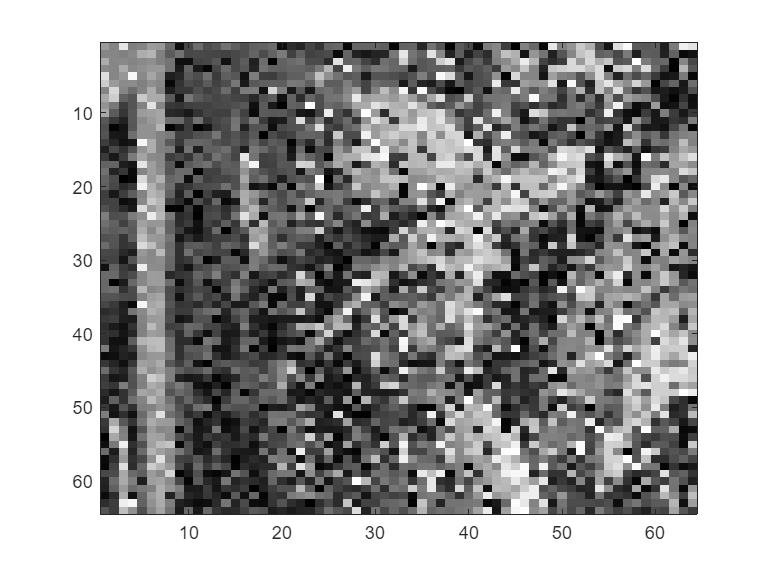


b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2);
lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

figure()
colormap(gray)
imagesc(nova_lenna)


mssim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255)

mssim = 0.3583

sound(y_inaudivel(fa*5:fa*15), fs)

Dessa forma, é possível ouvirmos um sinal limpo. Não há ruídos no áudio e para a percepção humana, a múscia está exatamente igual.

Apesar disso, vemos que a taxa de erros na transmissão é bem alto e gera um imagem com muito erro. É possível identificar a imagem, mas ela está bastante ruim.

# PARTE 4 - Marca d’água inaudível com BER baixa

Por fim, para melhorar a taxa de bits, iremos passar o sinal por um filtro Weiner. 

A ideia desse filtro é estimar processor aleatórios como a nossa mensagem de marca d'água. O filtro será aplicado antes da decodificação do sinal em bits. Iremos dividir o sinal que passou pelo filtro inverso de marca psicoacústica em trechos de 512 amostras. Para cada trecho iremos calcular o filtro Weiner correspondente e passar o sinal por ele. Depois dessa filtragem o sinal irá passar pela decodificador de imagem para verificarmos a eficácia desse processo.

Nfiltro = 50;
correlacao_v= xcorr(v,Nfiltro,'biased');

zs = zeros(2*Nfiltro,1);
pre_dem = zeros(length(musica),1);
saidaWiener = zeros(length(musica),1);

Nblocos = floor(length(musica)/512);

for i = (0: Nblocos-1)
    correlacao_z = xcorr(z(i*512+1: (i+1)*512), 2*Nfiltro, 'biased');
    
    autocorr_z = toeplitz(correlacao_z(2*Nfiltro+1:end));
    
    h = autocorr_z\correlacao_v;
    
    [saidaWiener(i*512+1: (i+1)*512), zs] = filter(h,1,z(i*512+1: (i+1)*512), zs);
    pot_Wiener = sum(saidaWiener(i*512+1: (i+1)*512).*saidaWiener(i*512+1: (i+1)*512))/512;
    
    if pot_Wiener > 0
        saidaWiener(i*512+1: (i+1)*512) = saidaWiener(i*512+1: (i+1)*512)/sqrt(pot_Wiener);
    end
    
end
pre_dem(1:end-Nfiltro) = saidaWiener(Nfiltro+1:end);

ym = reshape(pre_dem,Nb,32768);

alfam = transpose(ym)*c/Nb;
BER = sum(abs(sign(alfam) - am)/2)/length(am)

BER = 0.0011

b_chapeu = sign(alfam);
lenna_col_chapeu = num2str((b_chapeu + 1)/2,"%1.0f");


lenna_bin_chapeu = reshape(lenna_col_chapeu, 64*64, 8);
lenna_chapeu = bin2dec(lenna_bin_chapeu);
nova_lenna = reshape(lenna_chapeu, 64,64);

figure()
colormap(gray)
imagesc(nova_lenna)

mssim = ssim_index(lenna, nova_lenna, [0.01 0.03], matriz, 255)

mssim = 0.9778

## Conclusão

Por fim chegamos a situação mais prática, onde temos um sinal de marca d'água inaudível e com uma baixa taxa de erros de bits.

Vemos por fim que a imagem está muito boa, apesar de ter alguns erros em pixels. E se ouvirmos a música, não notaremos o ruído anterior. 

Esse processo é possível quando passamos a mensagem de banda estreita por um modular de achatamento de banda e por um filtro de limiar psicoacústico. Para decodificação do sinal, passamos a múcisa por um filtro inverso do limiar psicoacústico e por um filtro Weiner para estimar o pixel recebido naquele trecho de sinal . 

Com esse processo chegamos a uma imagem com MSSIM =  0.9778 e uma tava de erros BER = 0.0011